# Building Generalized Plants in Matlab

There are two different methods for building generalized plants in Matlab.  Matlab now recommends the command *connect*, and in fact requires it for some newer commands.  There is also a legacy command *sysic* that is essentially the same that I will use in some examples.  Editorial: I cannot understand why there are so many tools for this (there is *another* short-lived command called *iconnect*), and especially why they have deprecated a command that is IMO as good as the new one.

For both commands we will look at the classic mixed sensitivity synthesis problem.

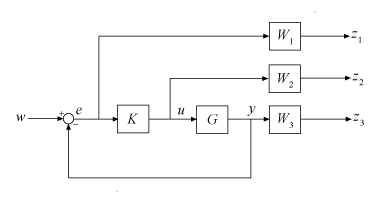

## Sysic

This provides a simple example of *sysic *usage, in particular for the famous mixed sensitivity design problem.

I'll start with a simple plant model and some basic weights.

G = tf(1,[1 1]);
Wt = 1/makeweight(2,3*1000,1e-3);
Wp = 1/makeweight(1e-3,1000,2);
Wu = tf(1/10);

Now the *sysic* command expects us to define three variables as follows.  *systemnames* includes the names of the transfer functions that make up the system.  They must be separated by spaces if there are more than 1.

systemnames = 'G Wp Wu Wt'; %Block name only

Now we have to define the inputs and outputs to the system by giving values to *inputvar* and *outputvar*.

inputvar = '[r;u]';
outputvar = '[Wp;Wu;Wt;r-G]'; %Strangely, the system outputs are just the name

Here the variables are partitioned as before, i.e. the input variables are listed as $[w ,u]^T$.  Now we need to give the inputs to each system.

input_to_G = '[u]';
input_to_Wp = '[r-G]';
input_to_Wu = '[u]';
input_to_Wt = '[G]';

That's the requirements!  Now we put it in action.

cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic

P =
 
  A = 
          x1     x2     x3     x4     x5
   x1     -1      0      0      0      0
   x2      0  -1732     64      0      0
   x3      1  -54.1      2      0      0
   x4      0      0      0  -1732     64
   x5     -1      0      0   54.1  0.001
 
  B = 
        r   u
   x1   0   1
   x2   0   0
   x3  -1   0
   x4   0   0
   x5   0   0
 
  C = 
           x1  x2  x3  x4  x5
   [+Wp]    0   0   1   0   0
   [+Wu]    0   0   0   0   0
   [+Wt]    0   0   0   0   1
   [+r-G]  -1   0   0   0   0
 
  D = 
             r    u
   [+Wp]     0    0
   [+Wu]     0  0.1
   [+Wt]     0    0
   [+r-G]    1    0
 
  E = 
       x1  x2  x3  x4  x5
   x1   1   0   0   0   0
   x2   0   1   0   0   0
   x3   0   0   0   0   0
   x4   0   0   0   1   0
   x5   0   0   0   0   0
 
Continuous-time state-space model.



Now let's test to see that it worked...

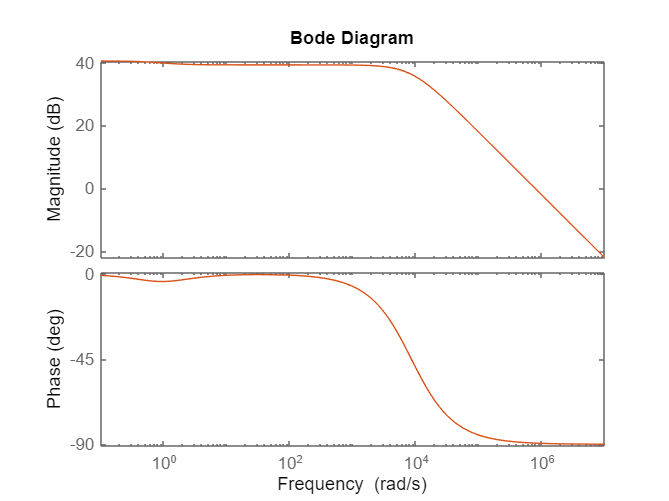

[Kms,CL,GAM] = mixsyn(G,Wp,Wu,Wt);
[Khinf,CL,GAM] = hinfsyn(P,1,1);
bode(Kms,Khinf)  %They're on top!

## Connect

For connect we need to establish the input and output signal names for each block and then patch them together.  We also need to use the *sumblk* command to work on summing junctions.

Let's start by building the summing junction.  Note that the signal names below are not really defined yet - that's OK so long as we are consistent.

Sum = sumblk('e = r-y');

Now build the I/O for each model in the system one-by-one.  Each system has an input (*.u) and output (*.y) parameter that are rarely used otherwise and accessed like a structure.  NOTE:  We do not deal with $K$ when making the generalized plant!

G.u = 'u';
G.y = 'y';
Wu.u = 'u';
Wu.y = 'z2';
Wp.u = 'e';
Wp.y = 'z1';
Wt.u = 'y';
Wt.y = 'z3';

Lastly we can run the command.  It needs the models above along with the list of input and output parameters.  Here is the basic usage:  `sysc = connect(sys1,...,sysN,inputs,outputs).`

P_connect = connect(G,Wp,Wu,Wt,Sum,{'r','u'},{'z1','z2','z3','e'})

P_connect =
 
  A = 
          x1     x2     x3     x4     x5
   x1     -1      0      0      0      0
   x2      0  -1732     64      0      0
   x3      1  -54.1      2      0      0
   x4      0      0      0  -1732     64
   x5     -1      0      0   54.1  0.001
 
  B = 
        r   u
   x1   0   1
   x2   0   0
   x3  -1   0
   x4   0   0
   x5   0   0
 
  C = 
       x1  x2  x3  x4  x5
   z1   0   0   1   0   0
   z2   0   0   0   0   0
   z3   0   0   0   0   1
   e   -1   0   0   0   0
 
  D = 
         r    u
   z1    0    0
   z2    0  0.1
   z3    0    0
   e     1    0
 
  E = 
       x1  x2  x3  x4  x5
   x1   1   0   0   0   0
   x2   0   1   0   0   0
   x3   0   0   0   0   0
   x4   0   0   0   1   0
   x5   0   0   0   0   0
 
Continuous-time state-space model.



Is is the same, but let me demonstrate by solving.

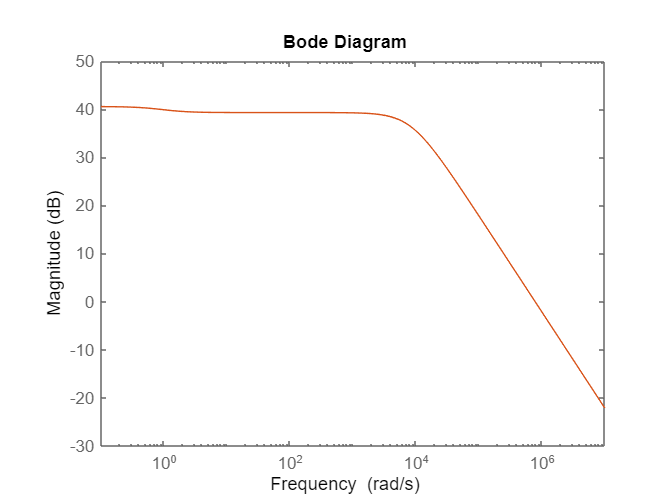

Kconnect = hinfsyn(P_connect,1,1);
bodemag(Kconnect,Khinf)